Limpieza inicial del doc

clc
clear
close all

Definir las constantes y medidas físicas

% Longitud de la barra en metros
Rbc = 0.3;
Rpe = 1;       % barra r_pe
Rod = 1.25;    % barra r_od
Rde = 1.1;     % barra r_de

rA = 0.1;      % engranaje A
rB = 0.3;      % engranaje B

% Parámetros de barra engranaje B
square_size = 0.03;      % tamaño del cuadrado

% distancias entre apoyos de barras
h = 0.16; 
d = 0.6;
h2 = 1.33;
d2 = 0;
distanciaY_op = 1.33;

Definición de parámetros cinemáticos

% Parámetros de tiempo
dt    = 0.01;  % Paso de tiempo en segundos
t_max = 100;   % Tiempo máximo de la simulación en segundos
t     = 0:dt:t_max;               % Vector de tiempo

% Crear vectores para almacenar los datos de la simulación
theta5 = zeros(1, t_max/dt+1);
theta4 = zeros(1, t_max/dt+1); 
theta3 = zeros(1, t_max/dt+1);

% Parámetros angulares engranaje A (rad)
theta1 = 0* pi/180;
w1     =    1000 * pi/180;
a1     =    720 * pi/180;

% Parámetros angulares engranaje B (rad)
theta2 = -( rA/rB ) * ( theta1 + w1*t + (1/2)*a1*(t.^2) );
w2     = -( rA/rB ) * ( w1 + a1*t );
speed  = 0;
angle  = 0;

Definir función de los circulos de engranajes A y B

% Dibujar un círculo estático en el centro de la figura
theta_circleA = linspace(0, 2*pi, 150);
x_circleA = 0.4 + 0.1*cos(theta_circleA);
y_circleA = 0.1*sin(theta_circleA);

theta_circleB = linspace(0, 2*pi, 150);
x_circleB = 0.3*cos(theta_circleB);
y_circleB = 0.3*sin(theta_circleB);

    Proceso de simulación

% Realizar la simulación
for i=1:length(t)-1

    theta3(i) = -atan2( h + Rbc * sin( theta2(i) ), -d + Rbc * cos( theta2(i) ) );
    
end

Calcular extremos de barras tras simulación

% Calcular las coordenadas X y Y de los extremos de la barra

% barra pe
Rpex_i = d;
Rpey_i = distanciaY_op - h;
Rpex_f = d - Rpe*cos(theta5);
Rpey_f = distanciaY_op - h + Rpe*sin(theta5);

% barra od
Rodx_i =  d;
Rody_i = -h;
Rodx_f = d + Rod*cos(theta3);
Rody_f = - h - Rod*sin(theta3);

% barra de
Rdex_i= Rpe*cos(theta4) + Rde*cos(theta4);
Rdey_i= Rpe + Rde*sin(theta3);
Rdex_f = Rody_f + Rde*cos(theta3);
Rdey_f = h + Rod + Rde*sin(theta3);

Gráfica de movimiento simulado

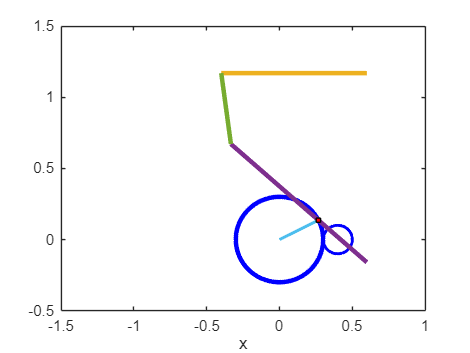

% Graficar la barra y su movimiento
figure(1);

% posición inicial del cuadrado
square_pos = [0,-1];  

for i=1:length(t)
    
    % Graficando engranaje B
    plot(x_circleB, y_circleB, 'b', 'LineWidth', 3);
    hold on
    % Graficando engranaje A
    plot(x_circleA, y_circleA, 'b', 'LineWidth', 2);
    % Graficando barra R_PE
    plot([Rpex_i Rpex_f(i)], [Rpey_i Rpey_f(i)], 'LineWidth', 3);
    % Graficando barra R_OD
    plot([Rodx_i Rodx_f(i)], [Rody_i Rody_f(i)], 'LineWidth', 3);
    % Graficando barra R_DE
    plot([Rodx_f(i) Rpex_f(i)], [Rody_f(i) Rpey_f(i)], 'LineWidth', 3);

    % Graficando barra engranaje B
    xb = [0, square_pos(1)];
    yb = [0, square_pos(2)];
    plot(xb,yb, 'LineWidth', 2);
    
    % Actualizando el ángulo
    angle = -speed + theta2(i);
    speed = abs( w2(i) )*dt;     % Velocidad giro

    % Graficando rectangulo
    rectangle('Position',[square_pos(1)-square_size/2, square_pos(2)-square_size/2, square_size, square_size],'FaceColor','r');
    square_pos = [0.3*cos(angle), 0.3*sin(angle)];
    hold off

    % Estbaleciendo los límites de la gráfica
    xlim([-1.5 1]);
    ylim([-0.5 1.5]);
    xlabel('x');
    ylabel('y');
    title('Movimiento Mecanismo');
    drawnow;
    pause(0);
end